clear all
%DATA FROM FRONT WHEEL SPEED : FL
fs = 100; %Hz
pre_data = readtable('baselineFrontData_01_30_25/cleaned_FL1CAN.csv', 'VariableNamingRule', 'modify', 'Delimiter', ',');

pre_data.target = pre_data.FrontLeftWheelSpeed;
data=table;
data.target = pre_data.target(~isnan(pre_data.target)) * 2; %scale by two for some reason??
data.Time = pre_data.Time(~isnan(pre_data.target));

data.target = data.target * -1;
pre_data.target = data.target;

post_data = readtable('cleanedDataFWSBoth_03052025');

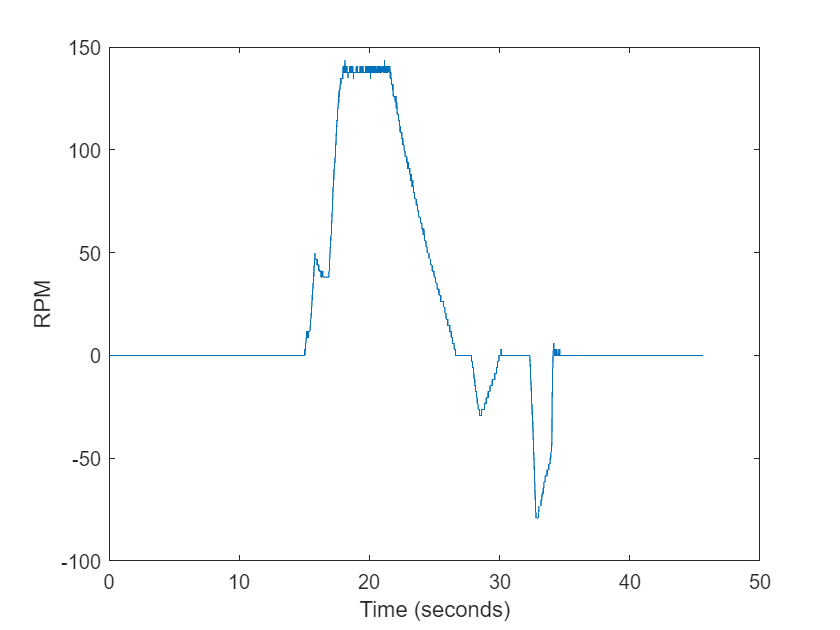

t_post = post_data.Time_s_(~isnan(post_data.FLSpeed_rpm_));
x_post = post_data.FLSpeed_rpm_(~isnan(post_data.FLSpeed_rpm_));

t = pre_data.Time(~isnan(pre_data.target));
x = pre_data.target(~isnan(pre_data.target));

% For post_data arrays:
valid_post = x_post < 10;       % Find indices where x_post is below 100
t_post_trim = t_post(valid_post); % Keep corresponding time values
x_post_trim = x_post(valid_post); % Keep the speed values
% 
% % For pre_data arrays:
valid_pre = x < 10;       % Find indices where x is below 100
t_trim = t(valid_pre);     % Keep corresponding time values
x_trim = x(valid_pre);     % Keep the speed values

figure;
plot(t, x)
xlabel('Time (seconds)')
ylabel('RPM')

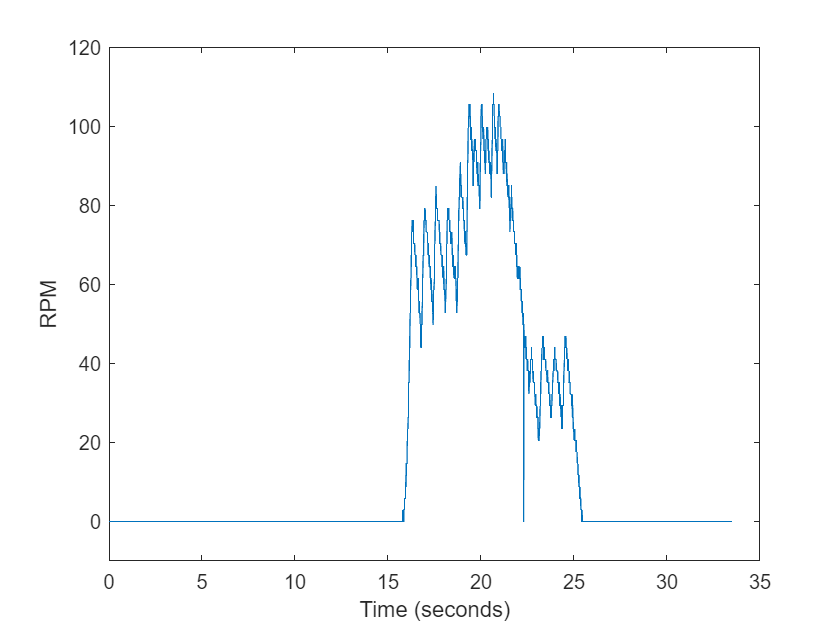

figure;
plot(t_post, x_post)
ylim([-10 120])
xlabel('Time (seconds)')
ylabel('RPM')

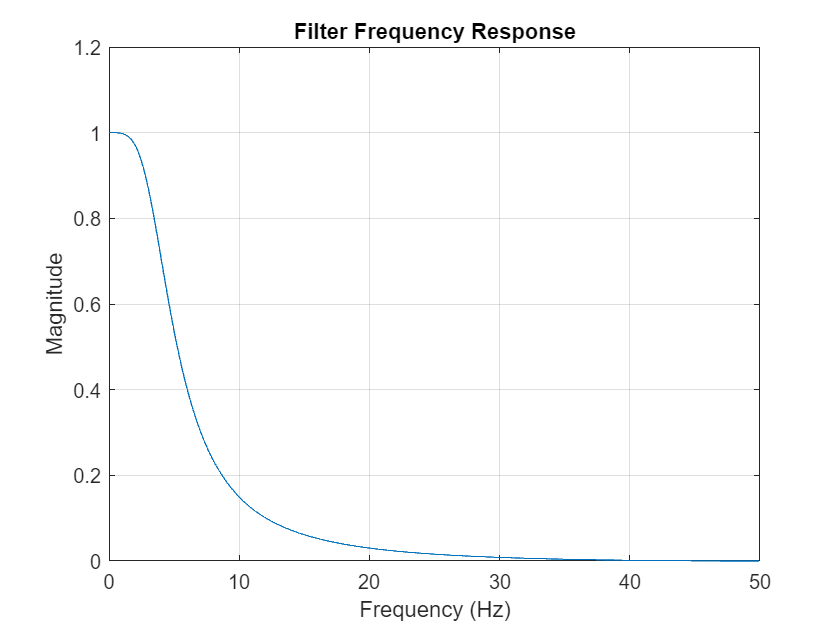

% 3-16 bandstop O2, 20 low pass O1
% b_combined_filter = [0.14410393 -0.419203    0.27539719  0.27539719 -0.419203    0.14410393 0.0];
% a_combined_filter = [1.0 -4.38041597  7.73480352 -6.8718419   3.06679259 -0.548742 0.0];
b = [0.0133592 0.0267184 0.0133592];
a = [ 1.0         -1.64745998  0.70089678];
alpha = 0.2;
%z = filter(alpha, [1 alpha-1], x);
%y = filter(alpha, [1 alpha-1], z);
%y_post = filter(alpha, [1 alpha-1], x_post);
y = filter(b, a, x);
y_post = filter(b, a, x_post);

b_freqz = b;
a_freqz = a;

[h, w] = freqz(b_freqz, a_freqz, 1024, fs);
figure;
plot(w, abs(h));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Filter Frequency Response');
grid on;

# **Pre Data**

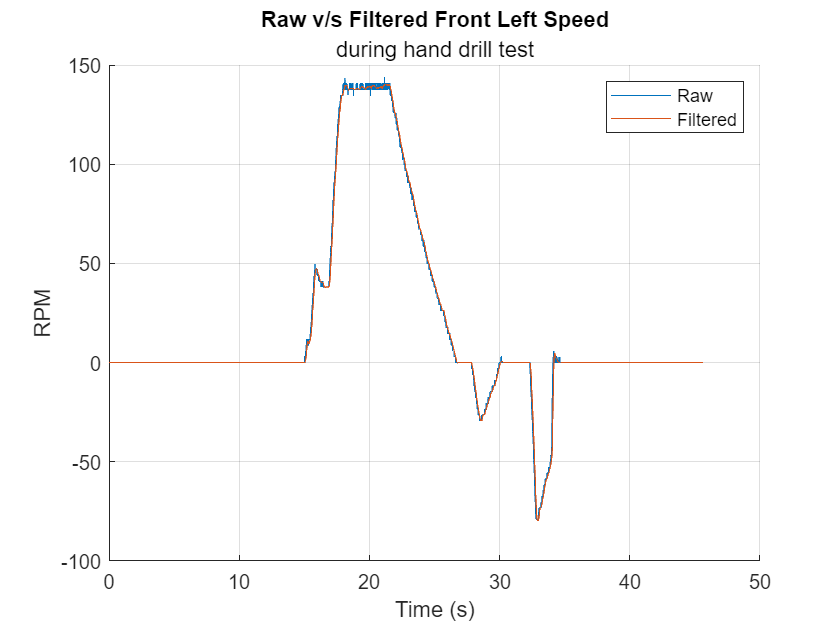

Ts = mean(diff(pre_data.Time(~isnan(pre_data.target))));

clf
hold on
%t = pre_data.Time(~isnan(pre_data.target));
%x = pre_data.target(~isnan(pre_data.target));
plot(t, x)
plot(t, y)
hold off
title("Raw v/s Filtered Front Left Speed")
subtitle("during hand drill test")
legend('Raw', 'Filtered')
xlabel('Time (s)')
ylabel('RPM')
grid on


% perform xcorr of this data
[r, lags] = xcorr(x, y, 500, 'normalized');

% max correlation:
[max_r, idx_max_r] = max(r);

time_index_lag = abs(lags(idx_max_r));

% time displacement of max correlation (i.e. lag of GPS speed):
max_correlation_lag = -1 * mean(diff(t)) * lags(idx_max_r)

max_correlation_lag = 0.0594

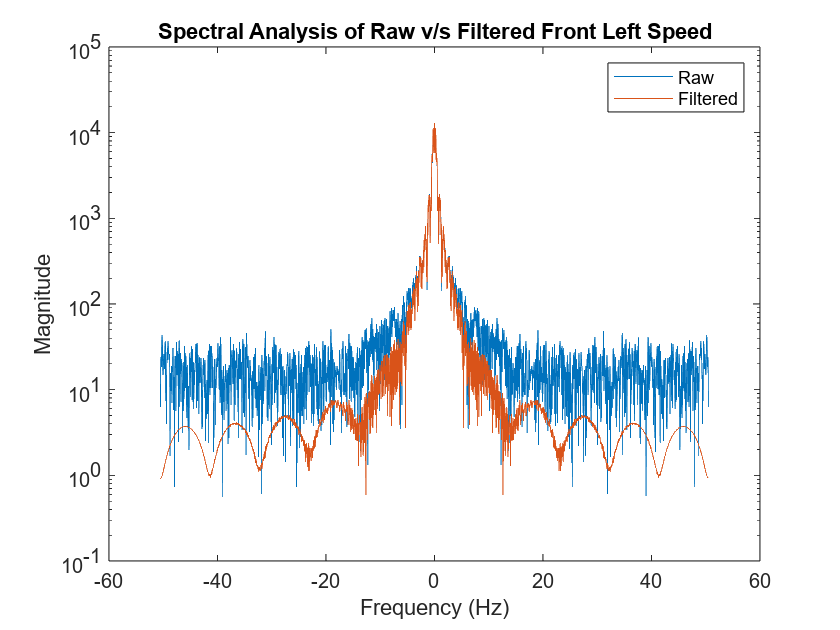



x_placeholder = x_trim;
z = fft(x_placeholder);
fs = 1/Ts;
f = (0:length(z)-1)*fs/length(z);
%plot(f,abs(y))

figure;
n = length(x_placeholder);
fshift = (-n/2:n/2-1)*(fs/n);
zshift = fftshift(z);
semilogy(fshift,abs(zshift))
hold on
xlabel('Frequency (Hz)')
ylabel('Magnitude')


title('Spectral Analysis of Raw v/s Filtered Front Left Speed')
x_placeholder = y(valid_pre);
z = fft(x_placeholder);
fs = 1/Ts;
f = (0:length(z)-1)*fs/length(z);
%plot(f,abs(y))

n = length(x_placeholder);
fshift = (-n/2:n/2-1)*(fs/n);
zshift = fftshift(z);
semilogy(fshift,abs(zshift))
legend('Raw', 'Filtered')
hold off

# **Post Data**

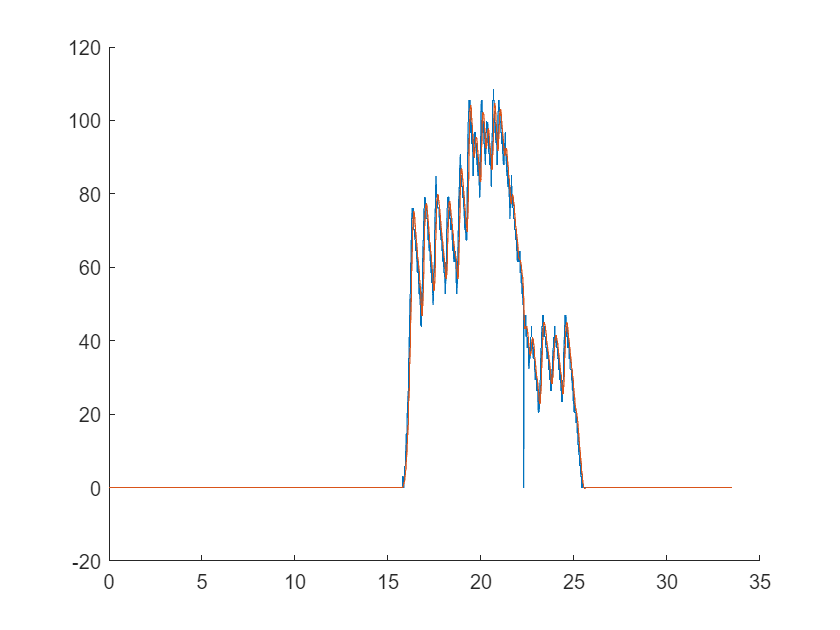

Ts = mean(diff(post_data.Time_s_(~isnan(post_data.FLSpeed_rpm_))));

clf
hold on
%t = pre_data.Time(~isnan(pre_data.target));
%x = pre_data.target(~isnan(pre_data.target));
plot(t_post, x_post)
plot(t_post, y_post)

% perform xcorr of this data
[r, lags] = xcorr(x, y, 500, 'normalized');

% max correlation:
[max_r, idx_max_r] = max(r);

time_index_lag = abs(lags(idx_max_r));

% time displacement of max correlation (i.e. lag of GPS speed):
max_correlation_lag = -1 * mean(diff(t)) * lags(idx_max_r)

max_correlation_lag = 0.0594

noise = x_post-y_post;
snr_post = snr(y_post, noise)

snr_post = 20.9323

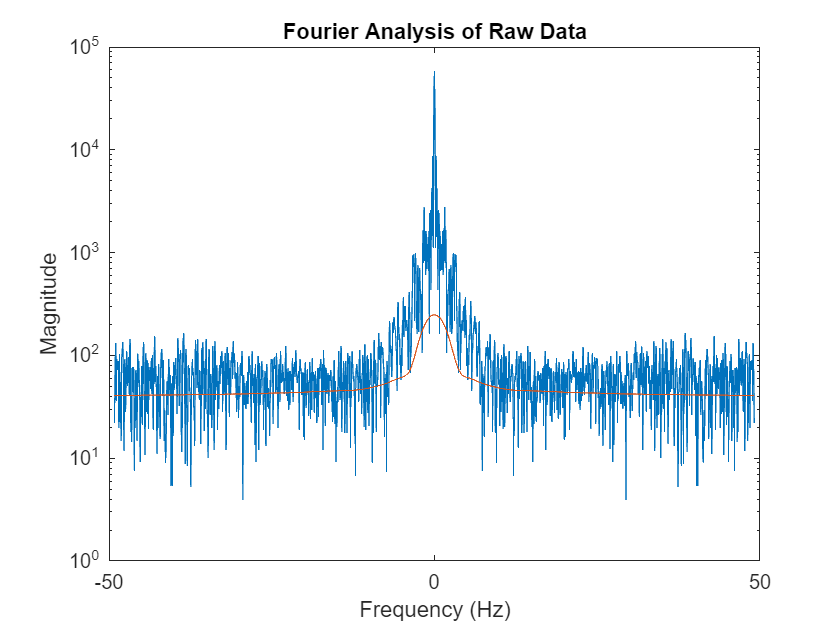



x_placeholder = x_post;
z = fft(x_placeholder);
fs = 1/Ts;
f = (0:length(z)-1)*fs/length(z);
%plot(f,abs(y))

figure;
n = length(x_placeholder);
fshift = (-n/2:n/2-1)*(fs/n);
zshift = fftshift(z);
semilogy(fshift,abs(zshift))
hold on
xlabel('Frequency (Hz)')
ylabel('Magnitude')


title('Fourier Analysis of Raw Data')
x_placeholder = y_post(valid_post);
z = fft(x_placeholder);
fs = 1/Ts;
f = (0:length(z)-1)*fs/length(z);
%plot(f,abs(y))

n = length(x_placeholder);
fshift = (-n/2:n/2-1)*(fs/n);
zshift = fftshift(z);
semilogy(fshift,abs(zshift))
hold off